clear



SoporteBielaA=readtable("MatLab cinetica\Reacciones soporte\A3-soporte-biela.txt","Delimiter"," ");

SoporteBielaA.Properties.VariableNames=["T","Fz","Fy","Fx","F","Mz","My","Mx","M","x"];
SoporteBielaB=readtable("MatLab cinetica\Reacciones soporte\B3-soporte-biela.txt","Delimiter"," ");

SoporteBielaB.Properties.VariableNames=["T","Fz","Fy","Fx","F","Mz","My","Mx","M","x"];
SoporteBielaC=readtable("MatLab cinetica\Reacciones soporte\C3-soporte-biela.txt","Delimiter"," ");

SoporteBielaC.Properties.VariableNames=["T","Fz","Fy","Fx","F","Mz","My","Mx","M","x"];



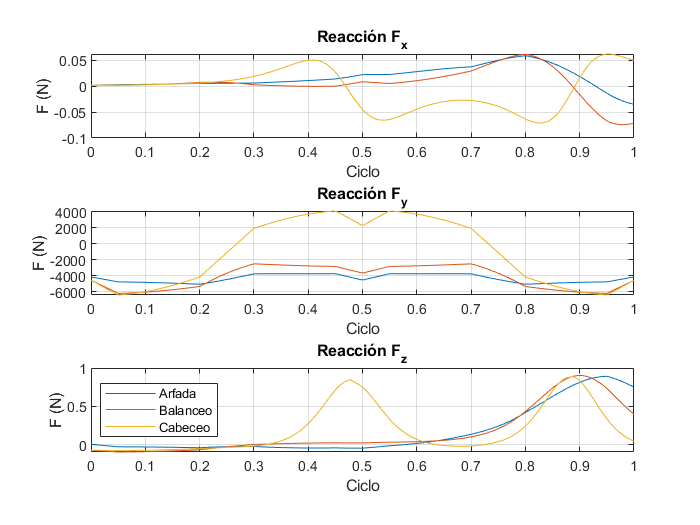


SoporteBielaAFx=SoporteBielaA.Fx;
SoporteBielaAFy=SoporteBielaA.Fy;
SoporteBielaAFz=SoporteBielaA.Fz;

SoporteBielaBFx=SoporteBielaB.Fx;
SoporteBielaBFy=SoporteBielaB.Fy;
SoporteBielaBFz=SoporteBielaB.Fz;

SoporteBielaCFx=SoporteBielaC.Fx;
SoporteBielaCFy=SoporteBielaC.Fy;
SoporteBielaCFz=SoporteBielaC.Fz;

max()


figure("Name","Biela soporte")
subplot(3,1,1)
plot(linspace(0,1,160),SoporteBielaAFx)
hold on
plot(linspace(0,1,160),SoporteBielaBFx)
plot(linspace(0,1,160),SoporteBielaCFx)
hold off
title('Reacción F_x')
%ylim([-35 35])
xlabel('Ciclo')
ylabel('F (N)')
grid on
subplot(3,1,2)
plot(linspace(0,1,160),SoporteBielaAFy)
hold on
plot(linspace(0,1,160),SoporteBielaBFy)
plot(linspace(0,1,160),SoporteBielaCFy)
hold off
title('Reacción F_y')
xlabel('Ciclo')
ylabel('F (N)')
grid on
subplot(3,1,3)
plot(linspace(0,1,160),SoporteBielaAFz)
hold on
plot(linspace(0,1,160),SoporteBielaBFz)
plot(linspace(0,1,160),SoporteBielaCFz)
hold off
title('Reacción F_z')
xlabel('Ciclo')
ylabel('F (N)')
grid on
legend("Arfada","Balanceo","Cabeceo","Location","best")